#  1.Introduction

This tutorial will demonstrate entropy and open circuit voltage (OCV) estimation process from charge/discharge data in step by step manner. After this tutorial you will be able to estimate open circuit voltage and entropy from your own experimental charge/discharge data   

The tutorial is provided as a series of MatLab live script cell, than can be modified and adjusted to your needs. Some basc understading in MatLab coding is assumed.

List of tutorials steps:

- 1.Introduction (you are here)

- 2.Experiment data

- 3.Experiment data conversion

- 4.Entropy and OCV estimation

- 5.Entropy and OCP estimation

## Brief introduction to MatLab live scripts

In case you are new to MatLab here is a brief introduction:

MatLab live script (just like this one) allows you to combine the code and enrich it with explanaition text. A live script is made up of code and text cells that can be executed step wise one by one (just like this one) or code cell bellow.

Hours_in_a_year = 24 * 365 

  To execute the code cell above you can click on the cell and click "Run Section" or use a keyboard shortcut "Control+Enter", to run all the cells use "F5" keyboard shortcut. Matlab automatically outputs of the code unless specified not to with ";" sign at end of code objects (example in cell below). 

Minutes_in_a_day = 60 * 24;

Code cell above defines a variable in the script denying the variable print. Variables defined in the code cells can be used in later code cells through out the live script file. This briefely covers the MatLab live script basics.

# 2.Experiment Data

In this section we will breif you on what are the experiment data requirements how should the experiment data excel file be formated, what it should contain and how it should be named to be converted to MatLab version and used without errors.

### Data requirements

-  Charge/Discharge at 25°C (required)

-  Charge/discharge at other than 25°C (at least 1 dataset is required for entropy estimation)

### Data file name designation

The process utlizes a speciffic experiment data file naming scheme to call the experiment datasets for the estimation process. Experiment data files names have:

- Cell code name "CellID" (Example: "TestCell") 

- Temperature in Celsius the experiment was performed at noted with "P" for positive and "N" for negative (sub zero) temperatures

- Experiment protocol if cell was discharged or charged noted with "S1" and "S3" respectively

Example of a name of a dataset that contains discharge data at  25°C: "TestCell_OCV_P25_S1"

Datasets with the same cell code name must be in the folder having the cell code name. Example folder: "TestCell_OCV"

### What should dataset contain

The charge/discharge experiments can have many different data types, here we are going to show the essential data that is required for the estimation porcess excecution:

- Voltage (V)

- Current step index 

- Charge capacity (Ah)

- Discharge capacity (Ah)

Above are the esential data columns in the experiment dataset for the estimation process to complete. Additionally, the dataset should have at least 1 data recording before applying current and after applying current. Below is a simple example of how the dataset should look like and what it should contain:

Example_dataset = readtable("TestCell_OCV\TestCell_OCV_P25_S1.xlsx")

Now that we know how the experiment data file should look like and what are the requirements the experiment data files can be formated accordingly. 

# 3. Experiment data conversion

With experiment data format in place we can convert the experiment data from excel to MatLab format.

We begin by calling the cell code name and temperatures at which the experiments were performed.

cellIDs = {'MCell'};  % Identifiers for each cell
order = [45 25 10 0];        % Temperatures for each 

Then we inform MatLab from which columns the data should be converted to MatLab format via column headers (**Note!: **they must be identical to what is in the excel files to be read). Then define the data column headers in MatLab as follows:

% Column headers to look for and convert to ".mat" file
headers = {'Step_Index','Voltage(V)',...
           'Charge_Capacity(Ah)','Discharge_Capacity(Ah)'};
% Corresponding MATLAB structure field names to use         
fields  = {'step','voltage','chgAh','disAh'};
% Field names to use for the four different testing scripts
stepFields = {'script1','script2','script3','script4'};

Now we can loop through the data with defined indentity information and convert the desired datasets from excel to MatLab format as following.

for theID = 1:length(cellIDs),    % loop over all cell types
  data = [];                      % clear data structure and start fresh
  for theFile = 1:length(order),  % loop over all temperatures
    dirname = cellIDs{theID};     % folder name in which to look for data
    ind = find(dirname == '_');   % if there is a "_", delete it
    if ~isempty(ind), dirname = dirname(1:ind-1); end
    if order(theFile) < 0,        % if temperature is negative, then
      OCVPrefix = sprintf('%s_OCV/%s_OCV_N%02d',... % look for this file
        dirname,cellIDs{theID},abs(order(theFile)));
    else                          % if temperature is positive, then
      OCVPrefix = sprintf('%s_OCV/%s_OCV_P%02d',... % look for this file
        dirname,cellIDs{theID},order(theFile));
    end

    for theScript = [1,3]          % process data from all four scripts
      OCVData = [];               % clear structure and start fresh
      for theField = 1:length(fields), % initialize empty fields
        OCVData.(fields{theField}) = [];
        chargeData.(fields{theField}) = [];
      end

      OCVFile = sprintf('%s_S%d.xlsx',OCVPrefix,theScript); % file name
      [~,sheets] = xlsfinfo(OCVFile);   % get names of sheets in file
      fprintf('Reading %s\n',OCVFile);  % status update for the impatient
      for theSheet = 1:length(sheets),  % loop over all sheets
        if strcmp(sheets{theSheet},'Info'), continue; end % ignore "Info"
        fprintf('Processing sheet %s\n',sheets{theSheet}); % status
        [num,txt,raw] = xlsread(OCVFile,sheets{theSheet}); % read data
        for theHeader = 1:length(headers), % parse out data that we care 
          ind = strcmp(txt(1,:),headers{theHeader}); % about
          OCVData.(fields{theHeader}) = [OCVData.(fields{theHeader});
            num(:,ind == 1)];
        end
      end
      data.(stepFields{theScript}) = OCVData; % save in structure
    end
    outFile = sprintf('%s.mat',OCVPrefix); % create output filename
    OCVData = data;
    save(outFile,'OCVData');               % save output file
  end
end

# 4. Entropy and OCV estimation

With experiment data in MatLab format, we can use it to estimate entropy coefficient and OCV. We begin by calling the cell code name and temperature, additionally we also define maximum and minimum voltages for plotting purposes as follows:

clear;
cellIDs = {'MCell'}; % Identifiers for each cell
% data files for each cell available at these temperatures
temps = {[45 25 10 0]};
           
% minimum and maximum voltages for each cell, used for plotting results       
minV = [2.5]; %minimum
maxV = [3.65];%maximum

Now we can call the estimation algorithm to estimate the entropy coefficient and OCV from desired datasets as follows:

     1    45
     1    25
     1    10



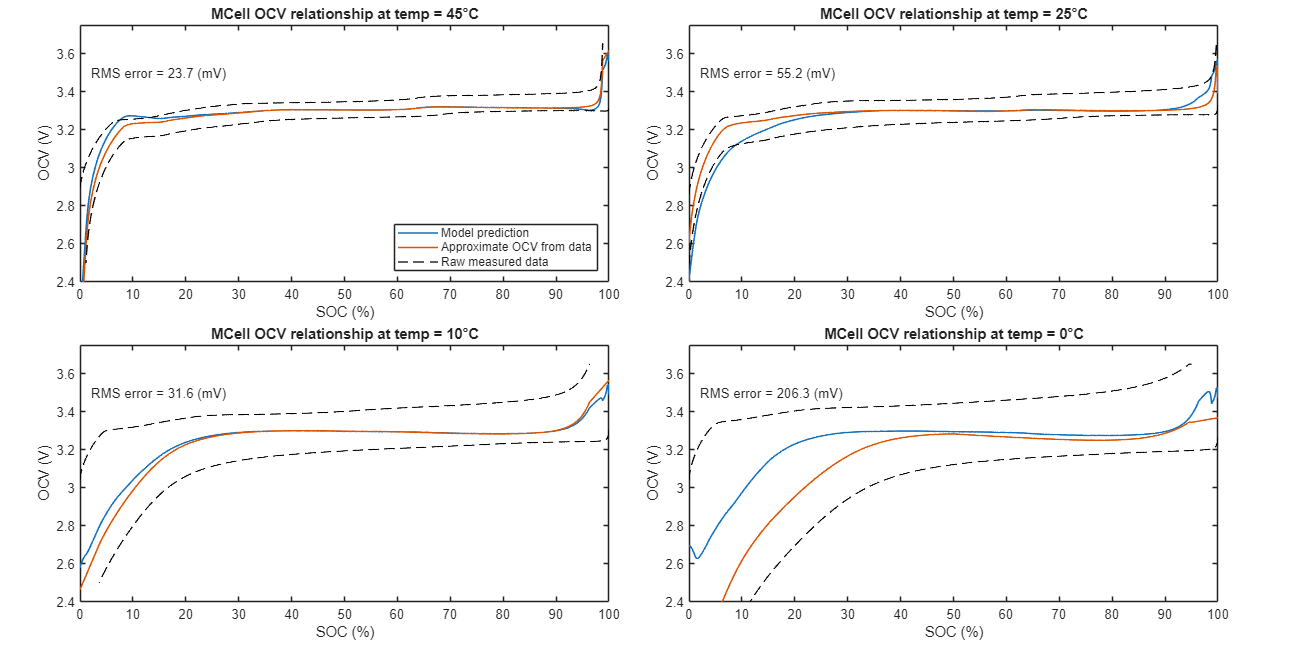

for theID = 1:length(cellIDs), % loop over all cells
  dirname = cellIDs{theID}; cellID = dirname;
  ind = find(dirname == '_'); % if there is a "_", delete it
  if ~isempty(ind), dirname = dirname(1:ind-1); end
  OCVDir = sprintf('%s_OCV',dirname); % folder in which to find data
  if ~exist(OCVDir,'dir'),
    error(['Folder "%s" not found in current folder.\n' ...
      'Please change folders so that "%s" is in the current '...
      'folder and re-run runProcessOCV.'],OCVDir,OCVDir); %#ok<SPERR>
  end
  
  filetemps = temps{theID}(:);  % data exists at these temperatures
  numtemps = length(filetemps); % number of data sets
  data = zeros([0 numtemps]);   % initialize data to zero

  for k = 1:numtemps,           % load the data files into the "data" var
    if filetemps(k) < 0,        % if temperature is negative, then
      filename = sprintf('%s/%s_OCV_N%02d.mat',... % look for this file
        OCVDir,cellID,abs(filetemps(k)));
    else                        % if temperature is positive, then
      filename = sprintf('%s/%s_OCV_P%02d.mat',... % look for this file
        OCVDir,cellID,filetemps(k));
    end
    load(filename);             % load OCV data file
    data(k).temp = filetemps(k);       % save temperature of test
    data(k).script1 = OCVData.script1; % save the scripts
    data(k).script3 = OCVData.script3;
  end

  % then, call "process_function" to do the actual data processing
  model = process_function_OCV(data,cellID,minV(theID),maxV(theID),1);
  save(sprintf('%smodel-ocv.mat',cellID),'model'); % save model file
end

Data is now procced and estimated entropy and OCV profiles can be compiled into tables and figures. This is done in the code cell bellow:

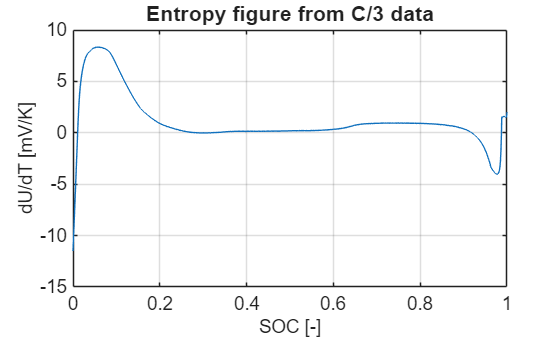

%Make OCV and Entropy tables as function of SOC
OCVTable = table(model.SOCaprox,model.OCVaprox)
dUdT_Table = table(model.SOC, model.OCVrel)
%'writebale' function can save the OCV, Entropy coefficients table as .csv or other format for 
% to be used as an import for equilibrium potential interpolation for electrodes

%writetable(OCVTable, 'MCell_OCV/MCell_OCV.csv')
%writetable(dUdT_Table, 'MCell_OCV/MCell_dUdT.csv')

%plot Entropy curve for visualization
figure
plot(model.SOC, (1000*model.OCVrel))
grid on
set(gca, "FontSize",14)
title('Entropy figure from C/3 data',FontSize=16)
xlabel('SOC [-]', FontSize=14)
ylabel('dU/dT [mV/K]',FontSize=14)

# 5. Entropy and OCP estimation

In this section we adapt the OCV estimation code to estimate open circuit potential (OCP) from half-cell charge/discharge, the process is esentially the same with minor changes and the data conversion and estimation process can be found bellow.

### Half-cells experiment data conversion

Input the half-cell code name "ID" and temperatures charge/discharge experiments were performed on half-cells

clear;
cellIDs = {'LFPhc'}; % Identifiers for each cell
order = [25];             % Temperatures for each 

% Column headers to look for and convert to ".mat" file
headers = {'Step_Index','Voltage(V)',...
           'Charge_Capacity(mAh)','Discharge_Capacity(mAh)'};
% Corresponding MATLAB structure field names to use         
fields  = {'step','voltage','chgmAh','dismAh'};%,
% Field names to use for the four different testing scripts
stepFields = {'script1','script2','script3','script4'};%

Bellow is the code to convert half-cell charge/discharge experiment:


for theID = 1:length(cellIDs),    % loop over all cell types
  data = [];                      % clear data structure and start fresh
  for theFile = 1:length(order),  % loop over all temperatures
    dirname = cellIDs{theID};     % folder name in which to look for data
    ind = find(dirname == '_');   % if there is a "_", delete it
    if ~isempty(ind), dirname = dirname(1:ind-1); end
    if order(theFile) < 0,        % if temperature is negative, then
      OCPPrefix = sprintf('%s_OCP/%s_OCP_N%02d',... % look for this file
        dirname,cellIDs{theID},abs(order(theFile)));
    else                          % if temperature is positive, then
      OCPPrefix = sprintf('%s_OCP/%s_OCP_P%02d',... % look for this file
        dirname,cellIDs{theID},order(theFile));
    end

    for theScript = [1,3]          % process data from all four scripts
      OCPData = [];               % clear structure and start fresh
      for theField = 1:length(fields), % initialize empty fields
        OCPData.(fields{theField}) = [];
        chargeData.(fields{theField}) = [];
      end

      OCPFile = sprintf('%s_S%d.xlsx',OCPPrefix,theScript); % file name
      [~,sheets] = xlsfinfo(OCPFile);   % get names of sheets in file
      fprintf('Reading %s\n',OCPFile);  % status update for the impatient
      for theSheet = 1:length(sheets),  % loop over all sheets
        if strcmp(sheets{theSheet},'Info'), continue; end % ignore "Info"
        fprintf('Processing sheet %s\n',sheets{theSheet}); % status
        [num,txt,raw] = xlsread(OCPFile,sheets{theSheet}); % read data
        for theHeader = 1:length(headers), % parse out data that we care 
          ind = strcmp(txt(1,:),headers{theHeader}); % about
          OCPData.(fields{theHeader}) = [OCPData.(fields{theHeader});
            num(:,ind == 1)];
        end
      end
      data.(stepFields{theScript}) = OCPData; % save in structure
    end
    outFile = sprintf('%s.mat',OCPPrefix); % create output filename
    OCPData = data;
    save(outFile,'OCPData');               % save output file
  end
end

Reading LFPhc_OCP/LFPhc_OCP_P25_S1.xlsx


Processing sheet Sheet1


Reading LFPhc_OCP/LFPhc_OCP_P25_S3.xlsx


Processing sheet Sheet1


### Entropy and OCP estimation 

Similarly as to OCV estimation here we define the half-cell code name "ID", operating temepratures and operating voltage limits for ploting purposes. The code is in cell bellow:

clear;
cellIDs = {'LFPhc'}; % Identifiers for each cell 
% data files for each cell available at these temperatures
temps = {[25]};
           
% minimum and maximum voltages for each cell, used for plotting results       
minV = [2.5];
maxV = [3.8];

Then we can run the OCP and entropy estimation algorithm to estimate OCP and entropy from half-cell charge/discharge datasets.

     1    25



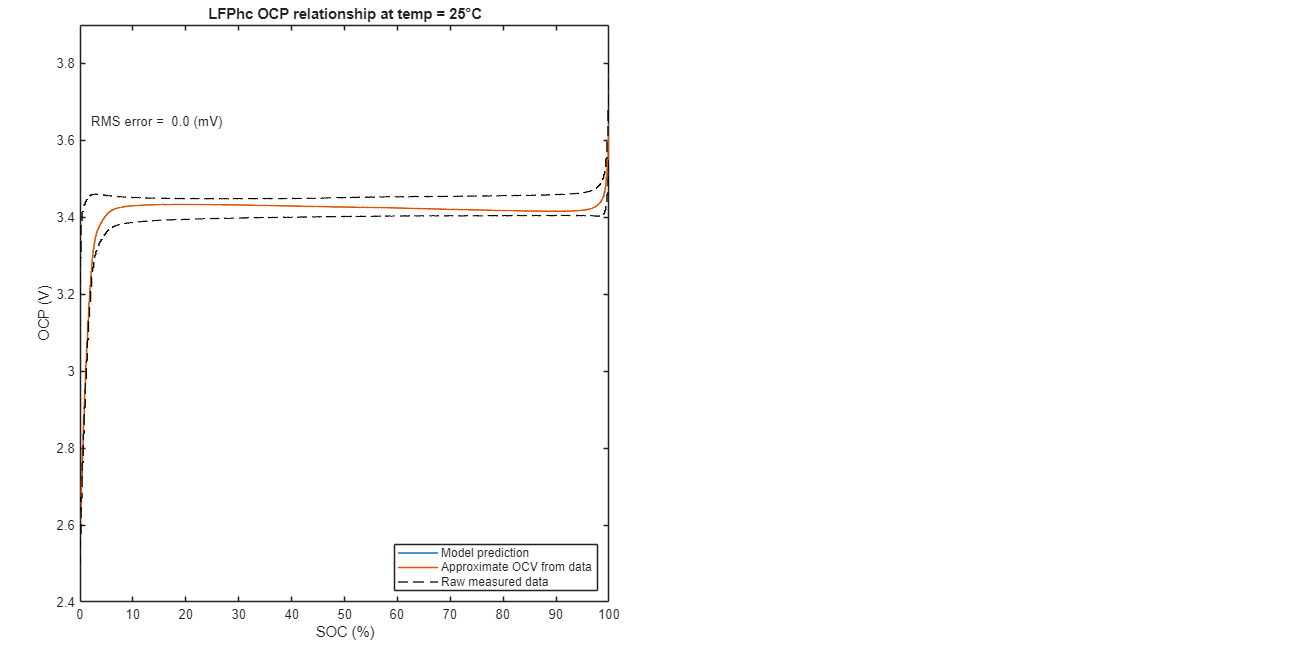

for theID = 1:length(cellIDs), % loop over all cells
  dirname = cellIDs{theID}; cellID = dirname;
  ind = find(dirname == '_'); % if there is a "_", delete it
  if ~isempty(ind), dirname = dirname(1:ind-1); end
  OCPDir = sprintf('%s_OCP',dirname); % folder in which to find data
  if ~exist(OCPDir,'dir'),
    error(['Folder "%s" not found in current folder.\n' ...
      'Please change folders so that "%s" is in the current '...
      'folder and re-run runProcessOCV.'],OCPDir,OCPDir); %#ok<SPERR>
  end
  
  filetemps = temps{theID}(:);  % data exists at these temperatures
  numtemps = length(filetemps); % number of data sets
  data = zeros([0 numtemps]);   % initialize data to zero

  for k = 1:numtemps,           % load the data files into the "data" var
    if filetemps(k) < 0,        % if temperature is negative, then
      filename = sprintf('%s/%s_OCP_N%02d.mat',... % look for this file
        OCPDir,cellID,abs(filetemps(k)));
    else                        % if temperature is positive, then
      filename = sprintf('%s/%s_OCP_P%02d.mat',... % look for this file
        OCPDir,cellID,filetemps(k));
    end
    load(filename);             % load OCV data file
    data(k).temp = filetemps(k);       % save temperature of test
    data(k).script1 = OCPData.script1; % save the four scripts
    data(k).script3 = OCPData.script3;
  end

  % then, call "processOCV" to do the actual data processing
  model = process_function_OCP(data,cellID,minV(theID),maxV(theID),1);
  save(sprintf('%smodel-ocp.mat',cellID),'model'); % save model file
end

Compilng the OCP and entropy estimation results into tables, and plot entropy profile.

%Makes a table variable with OCP and SOC
OCPTable = table(model.SOCaprox,model.OCVaprox)

OCPTable = 1000×2 table
    Var1      Var2 
    _____    ______

    0.001     2.634
    0.002    2.6171
    0.003    2.7141
    0.004    2.7213
    0.005     2.804
    0.006    2.8116
    0.007    2.8839
    0.008    2.8872
    0.009    2.9537
     0.01    2.9568
    0.011    3.0176
    0.012    3.0204
    0.013    3.0764
    0.014    3.0787
    0.015      3.13
    0.016    3.1326


dUdT_Table = table(model.SOC', model.OCVrel');

dUdT_Table = 1000×2 table
    Var1      Var2  
    _____    _______

    0.001    0.10536
    0.002    0.10469
    0.003    0.10856
    0.004    0.10885
    0.005    0.11216
    0.006    0.11246
    0.007    0.11536
    0.008    0.11549
    0.009    0.11815
     0.01    0.11827
    0.011     0.1207
    0.012    0.12081
    0.013    0.12306
    0.014    0.12315
    0.015     0.1252
    0.016     0.1253


%'writebale' function can save the OCP, dU/dT and SOC table as .csv or other format
%to be used as an import for equilibrium potential interpolation of electrodes

%writetable(OCPTable, 'LFPhc_OCP/LFPhc_OCP.csv')
%writetable(dUdT_Table, 'LFPhc_OCP/LFPhc_dUdT.csv')

# 6. Discussion

This toolbox provides scripts to estimate OCV, OCP and thier respective entropy profiles. It allows you to save them in your desired format, may it be cvs, excel or other typical table formats. The exported estimates then can be used as input in a moddeling and simulation software to create your own OCV, OCP and introduce entropy profiles for them. Feel free to use this toolbox with your own data to get your own open circuit voltage estimations 